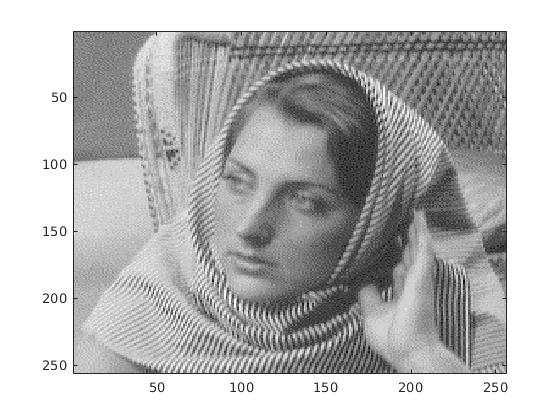

% 1-D decomposition
load woman
imagesc(X)
colormap(map)

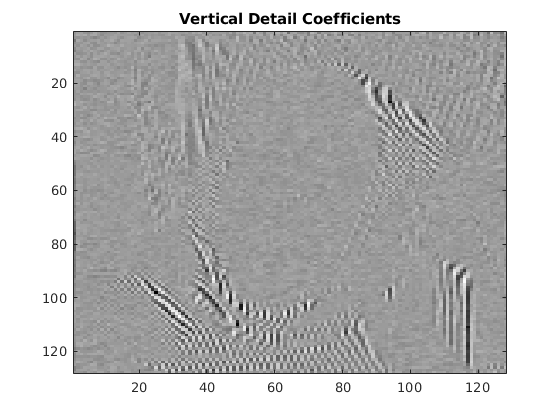

[cA,cH,cV,cD] = dwt2(X,'sym4','mode','per');
imagesc(cV)
title('Vertical Detail Coefficients')

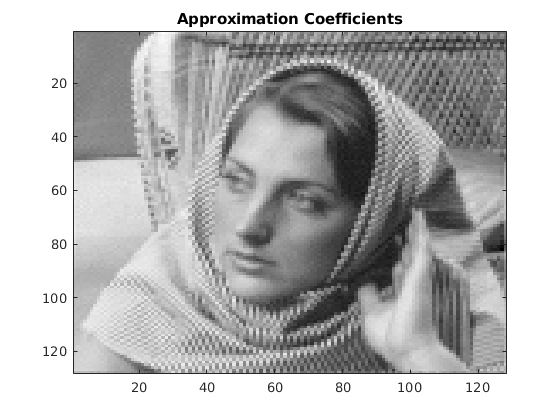

imagesc(cA)
title('Approximation Coefficients')

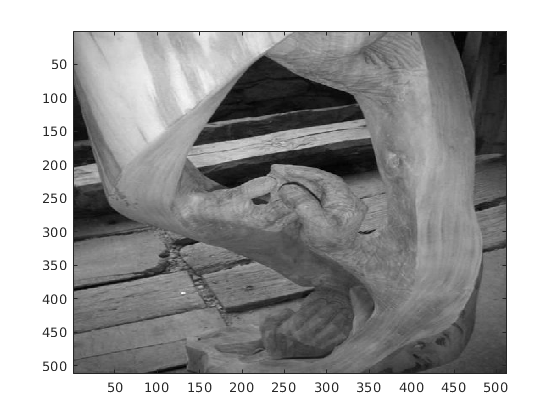

% 2-D decomposition
load sculpture
imagesc(X)
colormap gray

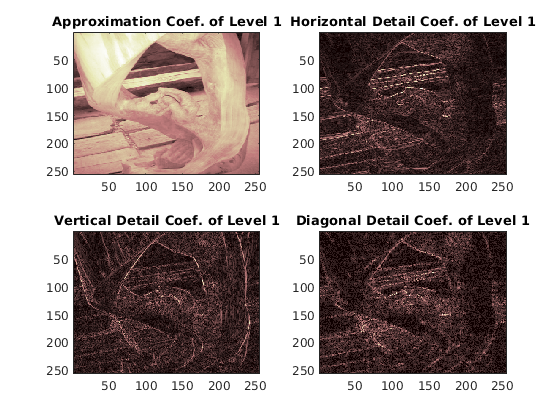

%Perform a level 2 wavelet decomposition of the image using the haar wavelet  
[c,s]=wavedec2(X,2,'haar');

%Extract the level 1 approximation and detail coefficients.
[H1,V1,D1] = detcoef2('all',c,s,1);
A1 = appcoef2(c,s,'haar',1);

%Use wcodemat to rescale the coefficients based on their absolute values. Display the rescaled coefficients.

V1img = wcodemat(V1,255,'mat',1);
H1img = wcodemat(H1,255,'mat',1);
D1img = wcodemat(D1,255,'mat',1);
A1img = wcodemat(A1,255,'mat',1);

subplot(2,2,1)
imagesc(A1img)
colormap pink(255)
title('Approximation Coef. of Level 1')

subplot(2,2,2)
imagesc(H1img)
title('Horizontal Detail Coef. of Level 1')

subplot(2,2,3)
imagesc(V1img)
title('Vertical Detail Coef. of Level 1')

subplot(2,2,4)
imagesc(D1img)
title('Diagonal Detail Coef. of Level 1')

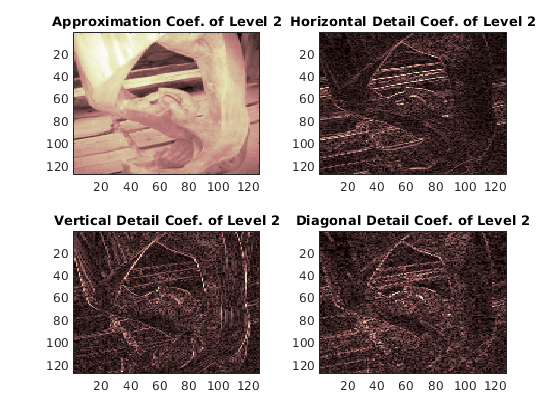


%Extract the level 2 approximation and detail coefficients.

[H2,V2,D2] = detcoef2('all',c,s,2);
A2 = appcoef2(c,s,'haar',2);

%Use wcodemat to rescale the coefficients based on their absolute values. Display the rescaled coefficients.

V2img = wcodemat(V2,255,'mat',1);
H2img = wcodemat(H2,255,'mat',1);
D2img = wcodemat(D2,255,'mat',1);
A2img = wcodemat(A2,255,'mat',1);

figure
subplot(2,2,1)
imagesc(A2img)
colormap pink(255)
title('Approximation Coef. of Level 2')

subplot(2,2,2)
imagesc(H2img)
title('Horizontal Detail Coef. of Level 2')

subplot(2,2,3)
imagesc(V2img)
title('Vertical Detail Coef. of Level 2')

subplot(2,2,4)
imagesc(D2img)
title('Diagonal Detail Coef. of Level 2')

addpath('/home/akshay/Desktop/CVC/Multi_target/Code/Multi-level_Sampling/spgl1-1.9')

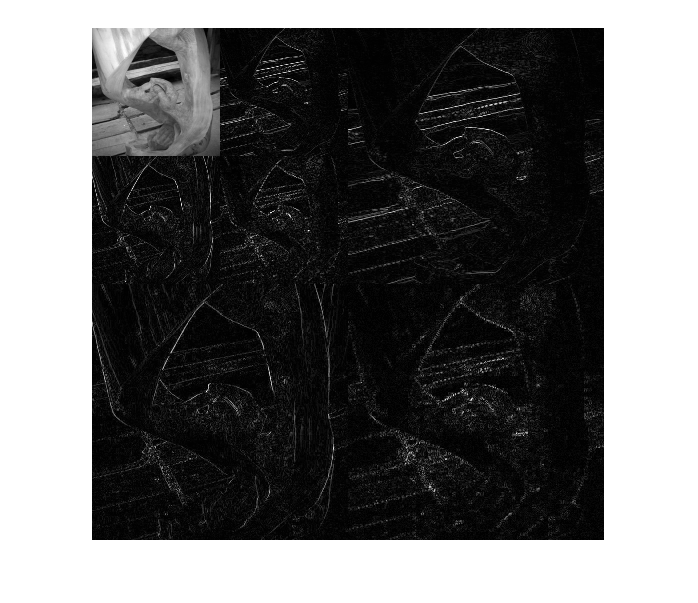


%img = imread('10-12813-01-2.bmp');
%img_gray = rgb2gray(img);
img_gray = X;
I_full = double(img_gray);
I = I_full(1:512,1:512)/255;
level = 2;
[C,S] = wavedec2(I,level,'haar');
figure
dec=plotwavelet2(C,S,level,'haar',255,'square');

wavelet=dec{1}/255;
figure
imshow(wavelet)

d=wavelet(1:128,1:128);
S

S =    128   128
   128   128
   256   256
   512   512


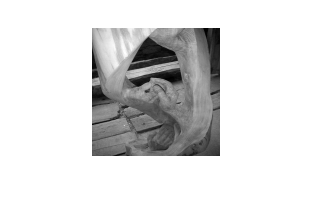

figure
imshow(d)

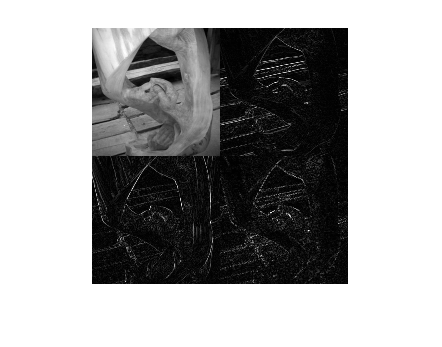

d2=wavelet(1:256,1:256);
figure
imshow(d2)

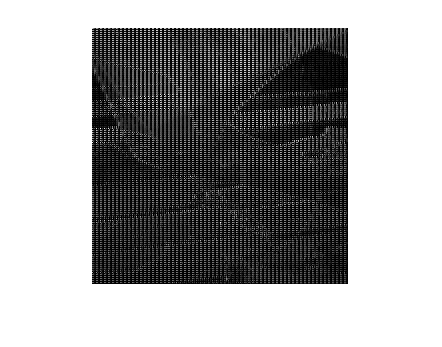

d2_original = waverec2(d2,S(1:3,:),'haar');
figure
imshow(d2_original)

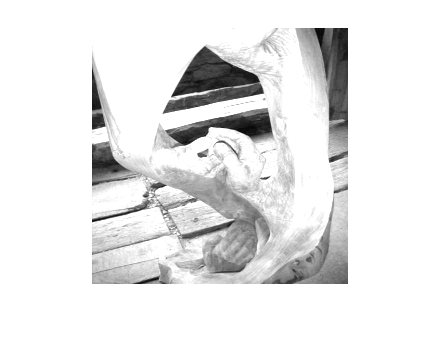

A1 = appcoef2(C,S,'haar',1);
figure
imshow(A1)

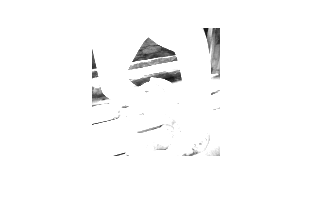


A2 = appcoef2(C,S,'haar',2);
figure
imshow(A2)  

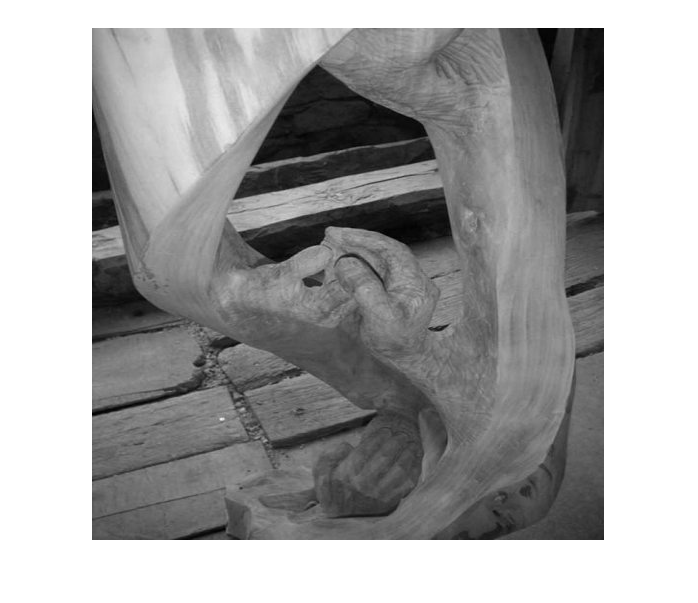

figure
imshow(X)